% running code to obtain w and b
[w0, b0, y, x] = Project1main();

Unrecognized function or variable 'Project1main'.


[n, dim] = size(x);
C = 10.^3;

% setting up soft margin SVM
Y = (y*ones(1,dim+1)).*[x, ones(n,1)];
%% obtaining initial guess for \xi
relu = @(w)max(w,0);
e = ones(n,1);
xi0 = relu(e-Y*[w0;b0]);

% setting up functions for ASM
%     f(x) = (1/2)x'Gx+CFx -> min
%     subject to Hxx >= yy
[d, ~] = size(w0);
G = zeros(d+n+1, d+n+1);
G(1:d,1:d) = eye(d);
F = [zeros(1,d+1) ones(1,n)];
xx = [w0; b0; xi0];
H = zeros(2*n, d+n+1);
H(1:n, 1:d+1) = Y;
H(1:n, end-n+1:end) = eye(n,n);
H(end-n+1:end, end-n+1:end) = eye(n,n);
yy = [ones(n,1);zeros(n,1)];
ffun = @(x)(1/2)*(x.'*G*x)+C*F*x;
gfun = @(x)(G*x+C*F.');
hfun = @(x)G;
% done setting up for ASM
% running ASM for w_
[asm_iter, l,pnorms,fs] = ASM(xx,ffun,gfun,hfun,H,yy,[]);

Stopped because the max number of iterations 1000 is performed


w_ = asm_iter(:,end);

% visualizing results
%% final plane

plotting(x,y,w_,'smsvm_plane.png');

Unrecognized function or variable 'x'.

%% norm of function over iterations
figure;
hold on;
grid;
niter = length(asm_iter);
plot((0:niter-2)',fs(1:niter-1),'Linewidth',2);
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('k','Fontsize',fsz);
ylabel('f','Fontsize',fsz);
saveas(gcf, 'smsvm_f.png')
%% norm of gradient over iterations
figure;
hold on;
grid;
niter = length(asm_iter);
plot((0:niter-1)',pnorms(1:niter),'Linewidth',2);
set(gca,'YScale','log');
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('k','Fontsize',fsz);
ylabel('||p||','Fontsize',fsz);
saveas(gcf, 'smsvm_p.png')

w = [-5.882156e-01,-1.291542e+00,-1.989383e+00], b = 1.980341e+00


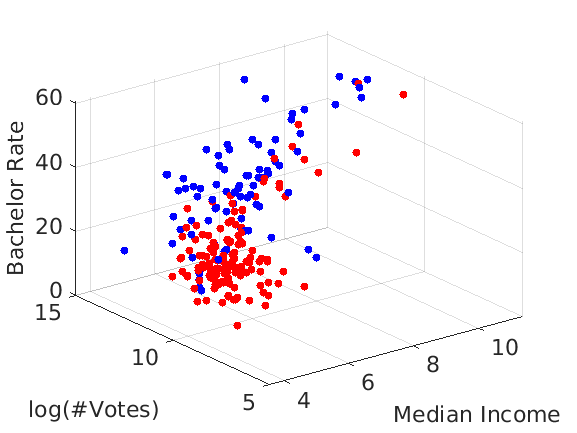

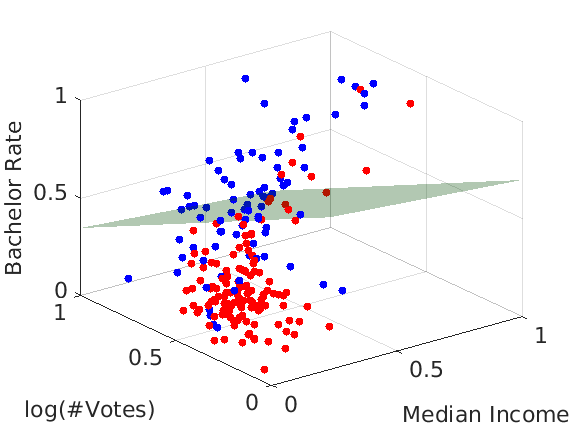

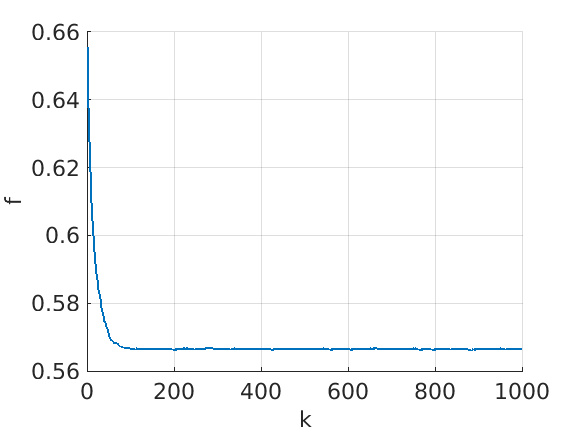

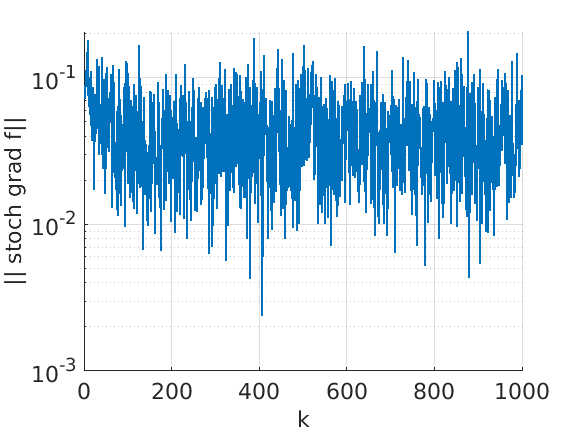

% now run code with 'CA-WA-NJ-NY-OR' data
% running code to obtain w and b
[w0, b0, y, x] = Project1main_allStates('CA-WA-NJ-NY-OR');


[n, dim] = size(x);
C = 10.^3;

% setting up soft margin SVM
Y = (y*ones(1,dim+1)).*[x, ones(n,1)];
%% obtaining initial guess for \xi
relu = @(w)max(w,0);
e = ones(n,1);
xi0 = relu(e-Y*[w0;b0]);

% setting up functions for ASM
%     f(x) = (1/2)x'Gx+CFx -> min
%     subject to Hxx >= yy
[d, ~] = size(w0);
G = zeros(d+n+1, d+n+1);
G(1:d,1:d) = eye(d);
F = [zeros(1,d+1) ones(1,n)];
xx = [w0; b0; xi0];
H = zeros(2*n, d+n+1);
H(1:n, 1:d+1) = Y;
H(1:n, end-n+1:end) = eye(n,n);
H(end-n+1:end, end-n+1:end) = eye(n,n);
yy = [ones(n,1);zeros(n,1)];
ffun = @(x)(1/2)*(x.'*G*x)+C*F*x;
gfun = @(x)(G*x+C*F.');
hfun = @(x)G;
% done setting up for ASM
% running ASM for w_
[asm_iter, l,pnorms,fs] = ASM(xx,ffun,gfun,hfun,H,yy,[]);

Stopped because the max number of iterations 1000 is performed


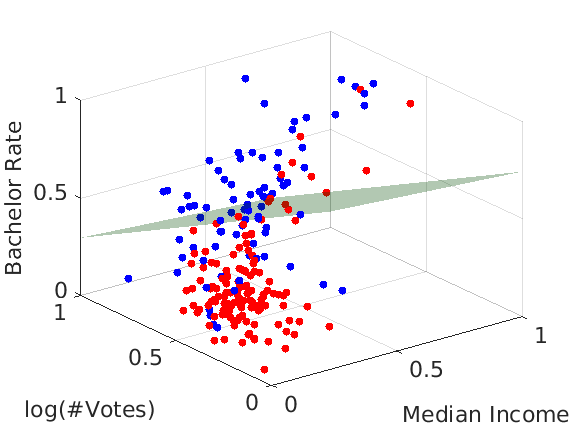

w_ = asm_iter(:,end);

% visualizing results
%% final plane
plotting(x,y,w_,'smsvm_plane_CA-WA-NJ-NY-OR.png');

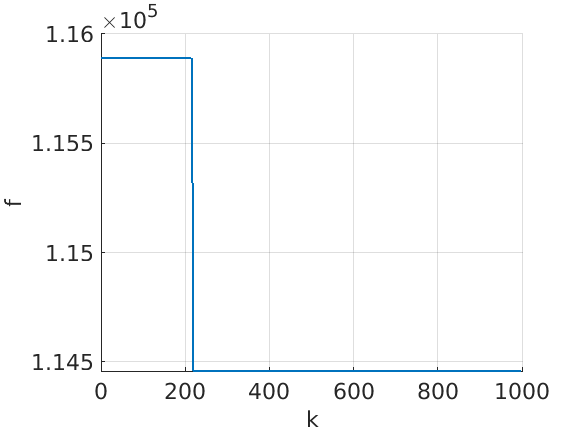

%% norm of function over iterations
figure;
hold on;
grid;
niter = length(asm_iter);
plot((0:niter-2)',fs(1:niter-1),'Linewidth',2);
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('k','Fontsize',fsz);
ylabel('f','Fontsize',fsz);
saveas(gcf, 'smsvm_f_CA-WA-NJ-NY-OR.png')

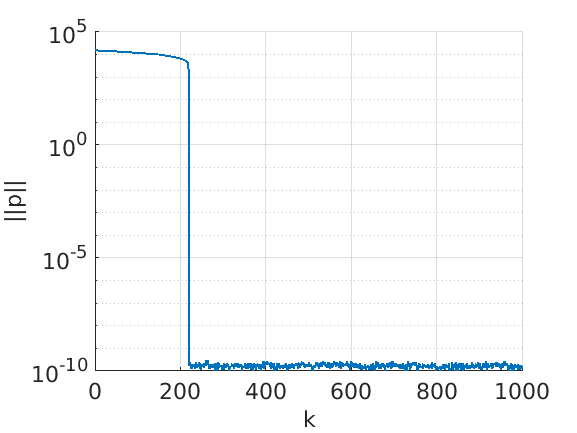

%% norm of gradient over iterations
figure;
hold on;
grid;
niter = length(asm_iter);
plot((0:niter-1)',pnorms(1:niter),'Linewidth',2);
set(gca,'YScale','log');
fsz = 16;
set(gca,'Fontsize',fsz);
xlabel('k','Fontsize',fsz);
ylabel('||p||','Fontsize',fsz);
saveas(gcf, 'smsvm_p_CA-WA-NJ-NY-OR.png')